# F1 Model Simulator

## Vehicle Dynamics

%% f1_vehicle_params.m
% MASTER initialization script - run only this one before simulating.
%
% Loads the Vehicle parameters (structure "veh") and also calls the
% Circuit/Timing scripts, so that a single run leaves the whole workspace
% ready: veh, the circuit curvature/speed limit, and the finish line geometry.
%
% Author: Julian Orozco - https://github.com/Julian9911 - MIT License
%
% SINGLE SOURCE of the values shared between the model and the scripts:
%   veh   mass and geometry
%   aero  air density, Cl, Af, CdA
%   pwr   engine, gearbox, wheel radius, rev limiter, shift thresholds
%   tire  rolling resistance (QSY) and grip of the limiters
%   brk   brake disc and brake split
% f1_speed_profile.m, the block dialogs (f1_link_block_params.m) and the MATLAB
% Function blocks (f1_link_function_params.m, via the flat aliases fp_*) all read
% from these structures. Use f1_scan_model_params.m to list any value still typed by hand.
%
% Execution order (do not change it: the last two depend on the file
% silverstone_centerline.csv, not on each other):
%   1. This script (vehicle parameters)
%   2. f1_track_curvature.m  (circuit: curvature, speed limit)
%   3. f1_finish_line_params.m (timing: finish line geometry)

%% --- Mass and geometry (Vehicle Body 3DOF, Dual Track variant) ---

veh.m             = 770;    % [kg] 2026 minimum mass (driver incl., fuel excl.) - CONFIRMED by regulation
veh.wheelbase     = 3.4;    % [m]  wheelbase, 2026 regulatory maximum           - CONFIRMED by regulation

veh.track_f       = 1.6;    % [m]  front track  - ESTIMATED (not officially published)
veh.track_r       = 1.6;    % [m]  rear track   - ESTIMATED (not officially published)

veh.cg_height     = 0.35;   % [m]  CG height    - ESTIMATED (vehicle-dynamics literature: 0.25-0.30 m)
veh.weight_dist_r = 0.55;   % [-]  mass fraction on the rear axle - ESTIMATED (~45/55 typical in single-seaters)

%% --- Aerodynamics ---
% Same values as the Vehicle Body and f1_aero_active.m (CdA_straight).

aero.rho          = 1.225;          % [kg/m^3] air density (Tair 288.15 K)
aero.Cl           = 3.2;            % [-]  downforce coefficient - SECONDARY SOURCES (ClA range 3.2-6.4 m2)
aero.Af           = 1.5;            % [m^2] frontal area         - SECONDARY SOURCES
aero.Cd_corner    = 0.73;           % [-]  drag coefficient of the corner mode (Vehicle Body) - same Cd as the block
aero.CdA_straight = 0.85;           % [m^2] straight mode (active aero) - CALIBRATED (must match CdA_straight in f1_aero_active.m)

%% --- Tires (Combined Slip Wheel 2DOF, or Dugoff Wheel 2DOF for the simple version) ---

% TODO: Magic Formula 6.2 / Dugoff coefficients.
% Starting point: use the built-in values of the block.
% Adjust here when the tire model is calibrated with our own data.

% Rolling resistance and grip used by f1_speed_profile.m (same as the model's wheels):
tire.QSY1      = 0.00699077564863536;   % rolling resistance coefficients of the wheel
tire.QSY3      = 0.00153535478298811;
tire.QSY7      = 0.89443879773793;
tire.Fz0_roll  = 4300;                  % [N] reference load of the rolling resistance
tire.mu_trac   = 1.4;                   % grip of the traction limiter (f1_engine_cmd)
tire.mu_brake  = 1.4;                   % grip of the brake limiter (f1_pedals_to_cmd)
tire.mu_pk_f   = 1.7;                   % [-] peak Fy/Fz, front axle (lateral table; friction circle of the limiters)
tire.mu_pk_r   = 1.8;                   % [-] peak Fy/Fz, rear axle (lateral table)
tire.Fznom      = 4000;                  % [N] nominal wheel load of the Vehicle Body and f1_lateral_tire_table
tire.FZMAX      = 15000;                 % [N] maximum wheel load of the 4 wheel blocks (raised from 8600: see parameter register T-06)

%% --- Sweep hook A (veh / aero / tire) and derived values ---
% f1_sensitivity_sweep.m sets the string sweepA (e.g. 'tire.mu_pk_f = tire.mu_pk_f*1.05;')
% to change base values for one run. Normal use: sweepA does not exist, nothing happens.
% Everything derived from the base values is computed AFTER the hook.
if exist('sweepA', 'var') && ~isempty(sweepA), eval(sweepA); end

% CG distances to each axle, derived from the mass distribution:
veh.a = veh.wheelbase * veh.weight_dist_r;        % [m] CG -> front axle
veh.b = veh.wheelbase * (1 - veh.weight_dist_r);  % [m] CG -> rear axle

% Yaw moment of inertia (Izz) - ESTIMATED with a vehicle-dynamics rule of
% thumb: (wheelbase / yaw radius of gyration)^2 ~ 7.5 for an F1 car (vs. ~3
% for a sedan/station wagon - F1 cars are more "point-like", with the mass
% concentrated near the CG).
veh.k_yaw = veh.wheelbase / sqrt(7.5);   % [m] yaw radius of gyration
veh.Izz   = veh.m * veh.k_yaw^2;         % [kg*m^2] yaw moment of inertia

aero.ClA = aero.Cl * aero.Af;      % [m^2] = 4.8
tire.mu_pk = tire.mu_pk_f;         % [-] peak used by the friction circle in f1_engine_cmd / f1_pedals_to_cmd

%% --- Lateral tire table (Vehicle Body, "Mapped slip angle") ---
% f1_lateral_tire_table.m generates alpha_brk, Cy_f_tab and Cy_r_tab, which the
% Vehicle Body uses as: Cy_f_data = Cy_f_tab, Cy_r_data = Cy_r_tab,
% alpha_f_brk = alpha_r_brk = alpha_brk. It opens a verification figure.
fprintf('\n--- Loading lateral tire table ---\n');


--- Loading lateral tire table ---


Front: Cy(0) = 160000 N/rad | peak mu_y = 1.70 at 9.7 degrees
Rear:  Cy(0) = 192000 N/rad | peak mu_y = 1.80 at 8.6 degrees
Table: 161 points, alpha from -0.80 to 0.80 rad


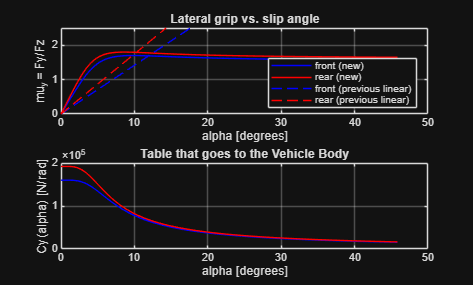

f1_lateral_tire_table


%% --- Powertrain (Mapped Motor + Open Differential) ---
% Same values as the Mapped SI Engine, the transmission and f1_shift_logic / f1_engine_cmd.

pwr.eng_scale = 0.91;     % engine torque factor (~750 kW at 12 000 rpm). MUST match the factor applied
                          % to f_tbrake in the Mapped SI Engine ("]*3.897*0.91") - CALIBRATED
pwr.Re        = 0.3515;   % [m] effective wheel radius
pwr.N_diff    = 4;        % [-] final drive
pwr.eta_tr    = 0.9;      % [-] transmission efficiency
pwr.gears     = [2.893 2.407 1.965 1.680 1.473 1.276 1.139];   % gears 2..8 (= N vector of the transmission) - TELEMETRY
pwr.rpm_up    = 11000;    % [rpm] upshift (same as f1_shift_logic)
pwr.rpm_dn    = 8500;     % [rpm] downshift (same as f1_shift_logic)
pwr.rpm_bpt   = [0 750 1053.57 1357.14 1660.71 1964.29 2267.86 2571.43 2875 3178.57 3482.14 3785.71 4089.29 4392.86 4696.43 5000] * 3.2;   % [rpm]
pwr.T_full    = [77.7345 77.7345 102.2072 120.9147 132.0395 143.8904 150.1347 155.4065 155.4065 156.9623 161.5149 166.2934 171.8297 173.7861 174.6472 174.6472] * 3.897;  % [N*m] maximum torque row of the map
pwr.rpm_lim_end   = 15000;   % [rpm] end of the limiter (torque reaches 0)
pwr.rpm_lim_taper = 1000;    % [rpm] width of the ramp (starts at 14000)

%% --- Brake disc (same values as the Disc brake of the 4 wheel blocks and f1_pedals_to_cmd) ---
brk.mu_k        = 0.4;      % [-]  mu_kinetic of the pads
brk.disk_abore  = 0.05;     % [m]  caliper piston bore
brk.Rm          = 0.177;    % [m]  mean disc radius
brk.num_pads    = 2;        % [-]
brk.max_torque  = 14000;    % [N*m] TOTAL brake torque, 4 wheels (f1_pedals_to_cmd)
brk.front_bias  = 0.6;      % [-]  fraction of the braking on the front axle

%% --- Sweep hook B (pwr / brk) ---
% Same idea as hook A, for the powertrain and the brake (string sweepB).
if exist('sweepB', 'var') && ~isempty(sweepB), eval(sweepB); end

%% --- Flat aliases for the MATLAB Function blocks (Parameter data) ---
% A Parameter in a MATLAB Function block reads a plain workspace variable
% (not a struct field), so each shared value gets a flat alias "fp_*".
% Do not edit them by hand: change the struct above and re-run this script.
fp_h_cg         = veh.cg_height;
fp_track        = veh.track_f;
fp_rho          = aero.rho;
fp_CdA_corner   = aero.Cd_corner * aero.Af;
fp_CdA_straight = aero.CdA_straight;
fp_mu_pk        = tire.mu_pk;
fp_mu_trac      = tire.mu_trac;
fp_mu_brake     = tire.mu_brake;
fp_gears        = pwr.gears;
fp_N_diff       = pwr.N_diff;
fp_eta_tr       = pwr.eta_tr;
fp_rpm_up       = pwr.rpm_up;
fp_rpm_dn       = pwr.rpm_dn;
fp_rpm_lim_ini  = pwr.rpm_lim_end - pwr.rpm_lim_taper;
fp_rpm_lim_end  = pwr.rpm_lim_end;
fp_brk_mu_k     = brk.mu_k;
fp_brk_bore     = brk.disk_abore;
fp_brk_Rm       = brk.Rm;
fp_brk_pads     = brk.num_pads;
fp_brk_maxT     = brk.max_torque;
fp_brk_front    = brk.front_bias;

%% --- Console summary (useful to check quickly after each edit) ---

fprintf('--- Vehicle parameters loaded ---\n');

--- Vehicle parameters loaded ---


fprintf('Total mass:        %.0f kg\n', veh.m);

Total mass:        770 kg


fprintf('Wheelbase:         %.2f m\n', veh.wheelbase);

Wheelbase:         3.40 m


fprintf('Track (f/r):       %.2f / %.2f m\n', veh.track_f, veh.track_r);

Track (f/r):       1.60 / 1.60 m


fprintf('CG (a / b):        %.2f / %.2f m\n', veh.a, veh.b);

CG (a / b):        1.87 / 1.53 m


fprintf('CG height:         %.3f m\n', veh.cg_height);

CG height:         0.350 m



%% --- Call the Circuit and Timing scripts ---
% Both are normal scripts (not functions) in the same folder, so they run
% just by typing their name, like a command.
%
% Note: f1_track_curvature.m opens a figure (the curvature plot) on every
% run - this is an expected side effect, not an error. If you later want a
% silent initialization, comment out the "Visual check" section inside that script.

% Pilot reference: true = RACING LINE (silverstone_raceline.csv, from
% f1_make_raceline.py); false = centerline (validated v1: lap 126.58 s).
useRaceline = true;

fprintf('\n--- Loading circuit (curvature, speed limit) ---\n');


--- Loading circuit (curvature, speed limit) ---


Total length: 5.857 km
Resampled points: 2929 (every 2.0 m)


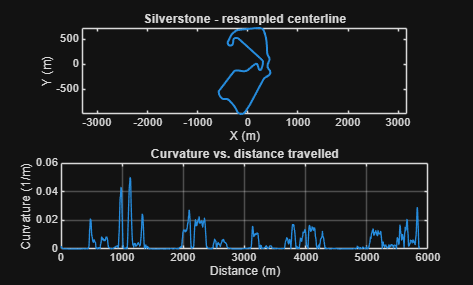

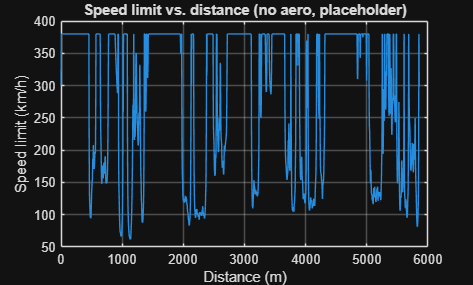

Saved: silverstone_curvature.mat (trackX, trackY, trackS, curvature, v_max_kmh)


f1_track_curvature


if useRaceline
    fprintf('\n--- Loading racing line (replaces the centerline as reference) ---\n');
    f1_load_raceline
end


--- Loading racing line (replaces the centerline as reference) ---


Racing line: 2894 points, 5788 m | curvature p95 0.0157 1/m | heading jump at the finish line 0.35 deg



fprintf('\n--- Computing reference speed profile (VelRef of the pilot) ---\n');


--- Computing reference speed profile (VelRef of the pilot) ---


Ideal lap of the profile (reachable): 91.21 s
Speed profile: min 17.8 m/s (64 km/h) at s = 1114 m | max 90.0 m/s


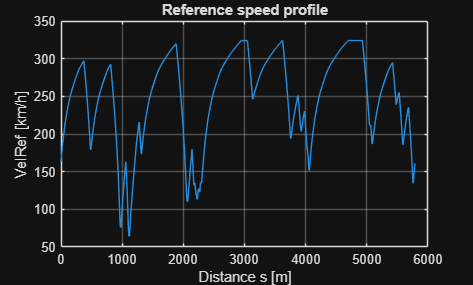

f1_speed_profile          % produces trackVref; must go AFTER the racing line


fprintf('\n--- Loading finish line geometry ---\n');


--- Loading finish line geometry ---


f1_finish_line_params

psi_o (initial heading): 0.907 rad (52.0 degrees)
Finish line at (-563.0, -515.7)
Direction of travel: (0.616, 0.788)
